clc; clear;  
  
% 定义X值，采样间隔为0.1  
X = 0:0.1:1;   
  
% 计算Y值  
Y = X.^3 + X;  
                        
% 使用差分方法近似计算曲率  
dX = diff(X); % X值的差分  
dY = diff(Y); % Y值的差分  

dYdX = dY ./ dX;  % 斜率  
% 使用差分方法近似计算二阶导数  
d2YdX2 = [0,diff(dYdX)]; 

curvature = (abs(d2YdX2)) ./ ((1 + dYdX.^2).^(3/2));  
   
% 计算曲线长度  
% 使用累加每段曲线的长度来近似整个曲线的长度  
% 使用公式：s ≈ Σ sqrt(dX^2 + dY^2)  
curveLength = cumsum(sqrt(dX.^2 + dY.^2));  
  
% 由于curvature和curveLength的第一个元素都是NaN（因为diff函数会去掉一个点），我们需要手动设置起始点的值  
curvature = [curvature]; % 假设起始点的曲率为0  
curveLength = [curveLength]; % 起始点的曲线长度为0  
  
% 显示结果  
disp('曲率:');  

曲率:


disp(curvature);  

         0    0.0191    0.0320    0.0369    0.0353    0.0299    0.0236    0.0178    0.0131    0.0095



disp('曲线长度:');  

曲线长度:


disp(curveLength);  

    0.1421    0.2886    0.4440    0.6136    0.8032    1.0188    1.2668    1.5538    1.8862    2.2704



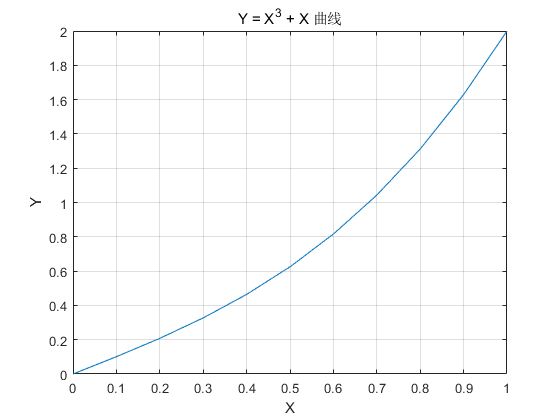

  
% 绘制曲线  
plot(X, Y);  
title('Y = X^3 + X 曲线');  
xlabel('X');  
ylabel('Y');  
grid on;  
hold on;  

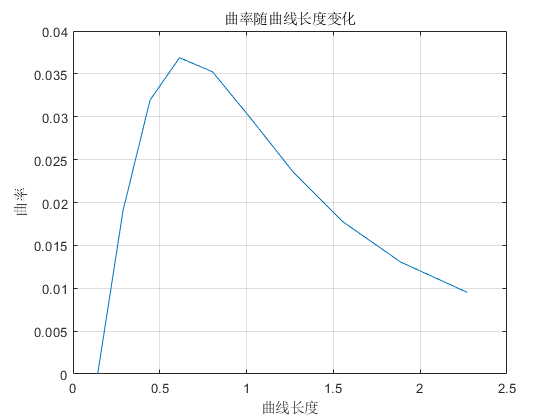


figure;
plot(curveLength, curvature);  
title('曲率随曲线长度变化');  
xlabel('曲线长度');  
ylabel('曲率');  
grid on;


D=0:0.6:3.0;
F=[2.2195 2.2167 2.2332 2.2305 2.2360 2.2222];

%插值求A对应的曲率
A=0:0.01:3.0;
%V=threesimple1(curveLength,curvature,A);
V=threesimple1(D,F,A);

D =     2.0000    0.5000         0         0
    0.5000    2.0000    0.5000         0
         0    0.5000    2.0000    0.5000
         0         0    0.5000    2.0000


h =     0.6000    0.6000    0.6000    0.6000    0.6000


A =     2.2195         0         0         0         0         0
    2.2167   -0.0047         0         0         0         0
    2.2332    0.0275    0.0268         0         0         0
    2.2305   -0.0045   -0.0267   -0.0297         0         0
    2.2360    0.0092    0.0114    0.0211    0.0212         0
    2.2222   -0.0230   -0.0268   -0.0212   -0.0177   -0.0129


g =     0.1608
   -0.1600
    0.0683
   -0.1608


M =          0
    0.1133
   -0.1316
    0.0930
   -0.1037
         0


function s=threesimple1(X,Y,x)
%        自然边界条件函数 
%        s函数表示三次样条插值函数插值点对应的函数值
%        根据三次样条参数函数求出的D,h,A,g,M
%        x表示求解插值点函数点，X为已知插值点        
         [D,h,A,g,M]=threesimple(X,Y)
         n=length(X); m=length(x);    
         for t=1:m
            for i=1:n-1
               if (x(t)<=X(i+1))&&(x(t)>=X(i))
                  p1=M(i,1)*(X(i+1)-x(t))^3/(6*h(i));
                  p2=M(i+1,1)*(x(t)-X(i))^3/(6*h(i));
                  p3=(A(i,1)-M(i,1)/6*(h(i))^2)*(X(i+1)-x(t))/h(i);
                  p4=(A(i+1,1)-M(i+1,1)/6*(h(i))^2)*(x(t)-X(i))/h(i);
                  s(t)=p1+p2+p3+p4; 
                  break;
               else
                   s(t)=0; 
               end
            end
         end
end


function [D,h,A,g,M]=threesimple(X,Y)
%        自然边界条件的三次样条函数(第二种边界条件)
%        此函数为M值求值函数
%        D,h,A,g,M输出量分别为系数矩阵D，插值宽度h，差商表A，g值,M值 
         n=length(X); 
         A=zeros(n,n);A(:,1)=Y';D=zeros(n-2,n-2);g=zeros(n-2,1);
         for  j=2:n
            for i=j:n
                A(i,j)=(A(i,j-1)- A(i-1,j-1))/(X(i)-X(i-j+1));
            end
         end
         
         for i=1:n-1
             h(i)=X(i+1)-X(i);
         end
         for i=1:n-2
             D(i,i)=2;
             g(i,1)=(6/(h(i+1)+h(i)))*(A(i+2,2)-A(i+1,2));
         end
         for i=2:n-2
             u(i)=h(i)/(h(i)+h(i+1));
             n(i-1)=h(i)/(h(i-1)+h(i));
             D(i-1,i)=n(i-1);
             D(i,i-1)=u(i);             
         end
         M=D\g;
         M=[0;M;0];         
end

